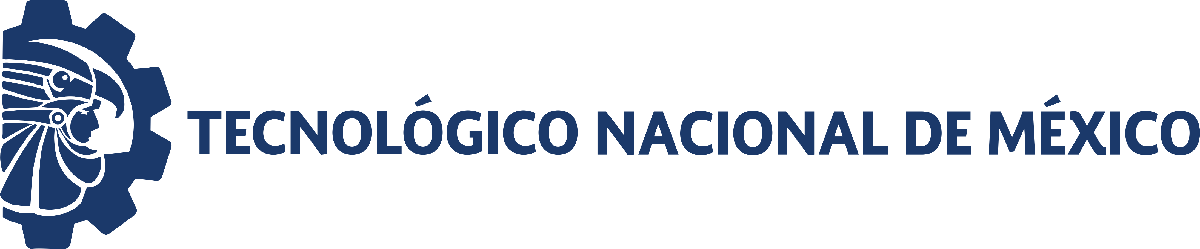                                 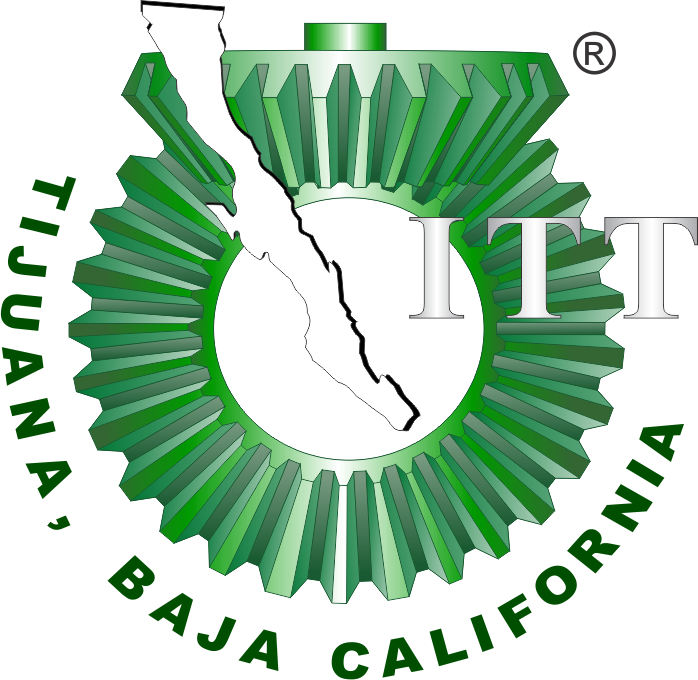

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: **Nombres y Apellidos**

Número de control: **12345678**

Correo institucional: **xxx.xxx@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta al escalón

Signal = 'Step';
set_param('Sistema/S1','sw', '1');
set_param('Sistema/Pao(t)', 'sw', '1');
x1 = sim(file, parameters);

## Respuesta al impulso

## Respuesta a la rampa

## Respuesta a la función sinusoidal